# **Non-Weighted Models and Signifcance Testing**

## **Consolidating the age data**

Here we import the full Age vs Distance dataset and consildate the data into one datapoint every 50km and also combine the errors by taking the weighted average of the errors and also adding the standard deviation of all the points in the bin

clear;
chain = 'HI';
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy.txt'));
s = 50;% bin size

%keep original data
x0 = dat(:,1);
y0 = dat(:,2);
err0 = dat(:,3);
type0 = dat(:,4);

%allocate storage
x_bar = [];
y_bar = [];
err_bar = [];
bin_type = [];
K_data = [];
% Begin the binning process
for bin = s:s:max(x0)+s;
    % sort data into bins
    points = find(x0>=(bin-s) & x0<bin); % specify index values for points in the given dist range
    x = x0(points);
    y = y0(points);
    err = err0(points);
    type = type0(points);
    n = length(x);
    if ((sum(type) == 0) & (isempty(type) == 0)) % when all data in a bin is obs
        [x2, y2, err2] = binning.get_weighted_average(x, y, err);
        x_bar = [x_bar; x2];    y_bar = [y_bar; y2];    err_bar = [err_bar; err2]; bin_type = [bin_type; 0];
    elseif ((sum(type) == n) & (isempty(type) == 0)) % when all data in a bin is Ar/Ar
        [x2, y2, err2] = binning.get_weighted_average(x, y, err);
        x_bar = [x_bar; x2];    y_bar = [y_bar; y2];    err_bar = [err_bar; err2]; bin_type = [bin_type; 1];
    elseif ((sum(type) == 2*n) & (isempty(type) == 0)) % when all data in a bin is K/Ar
        [x2, y2, err2] = binning.get_weighted_average(x, y, err);
        x_bar = [x_bar; x2];    y_bar = [y_bar; y2];    err_bar = [err_bar; err2]; bin_type = [bin_type; 2];
    else % When there is some combination of obs, Ar/Ar, and K/Ar data in a bin
        [obs, A, K] = binning.sort_data_by_type(x, y, err, type); %sort the data by type
        if (isempty(obs) == 0) % check if there's observed data
            x_obs = obs(:,1);  y_obs = obs(:,2);    err_obs = obs(:,3);
            [x2, y2, err2] = binning.get_weighted_average(x_obs, y_obs, err_obs); % bin only the observed ages
            x_bar = [x_bar; x2];    y_bar = [y_bar; y2];    err_bar = [err_bar; err2]; bin_type = [bin_type; 0];
        end
        if (isempty(A) == 0) % check if there's Ar/Ar data
            x_A = A(:,1);   y_A = A(:,2);   err_A = A(:,3); n_A = length(x_A);
            [x2, y2, err2] = binning.get_weighted_average(x_A, y_A, err_A); % bin only the Ar/Ar data
            x_bar = [x_bar; x2];    y_bar = [y_bar; y2];    err_bar = [err_bar; err2]; bin_type = [bin_type; 1];
        end
        if (isempty(K) == 0) % check if there's K/Ar data
            n_K = length(K(:,1));   K_type = ones(n_K,1).*2;
            K = [K K_type];
            K_data = [K_data; K]; % exclude K/Ar data and store in a separate file
        end
    end
end

%manually bin specific points

HI: 30:31

LV old: 18:19

RU old: 17:18

RU2: 12:13

SA : 12:13

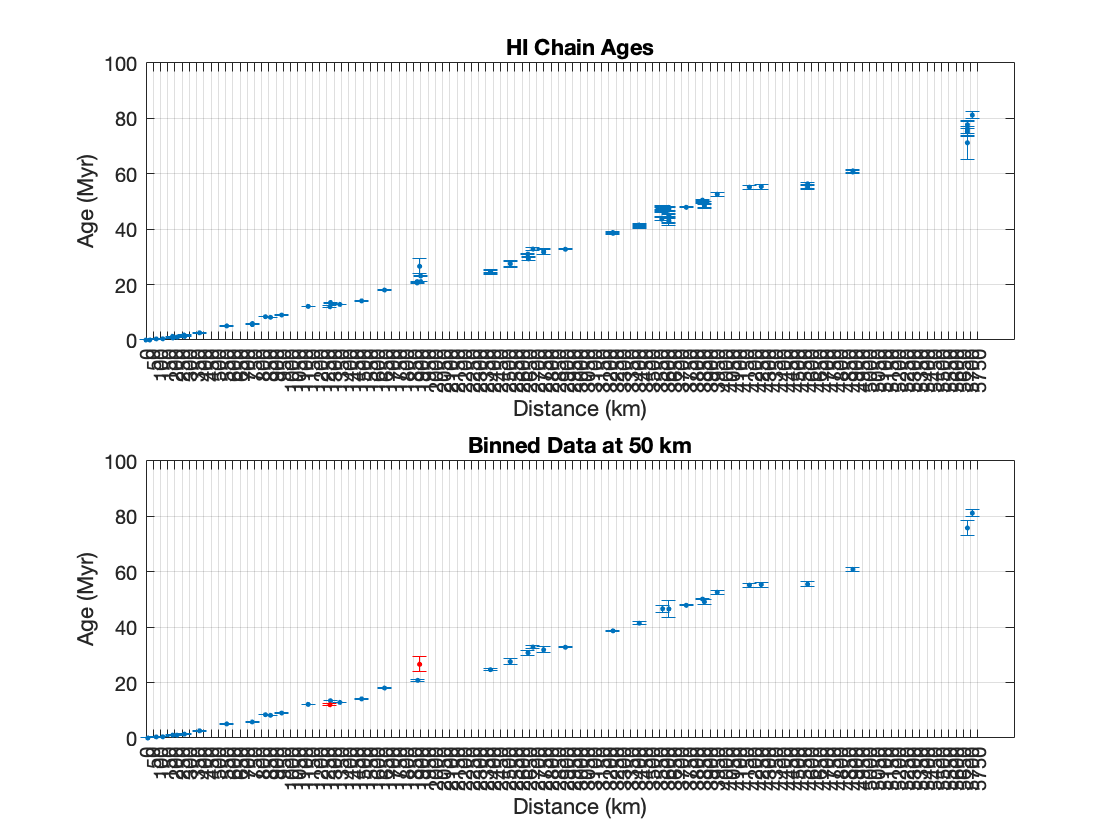

% v1 = 12;
% v2 = 13;
% x1 = x_bar(v1:v2);
% y1 = y_bar(v1:v2);
% err1 = err_bar(v1:v2);
% n1 = length(x1);
% w1 = 1./err1.^2;
% n1_eff = (sum(w1).^2)./sum(w1.^2);
% 
% 
% x1 = sum(x1.*w1)/sum(w1);
% y1 = sum(y1.*w1)/sum(w1);
% sy = sum(y1.*w1);
% sw = sum(w1);
% syy = sum(w1.*y1.^2);
% err1 = sum(err1.*w1)./sum(w1) + (sw.*syy - sy.^2)./(((n1-1)./n1).*sw.^2);
% 
% x_bar(v1) = x1;
% y_bar(v1) = y1;
% err_bar(v1) = err1;
% 
% x_bar(v2) = [];
% y_bar(v2) = [];
% err_bar(v2) = [];
% bin_type(v2) = [];

%expoort as a text file
A = table(x_bar,y_bar,err_bar, bin_type);
%writetable(A,strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'),'Delimiter','\t','WriteVariableNames',false);

B = table(K_data);
%writetable(B,strcat('chain_ages/', chain, '_K_ages_removed.txt'),'Delimiter','\t','WriteVariableNames',false);

%plot results over original dataset
clear figure;
figure(1);
subplot(211);
errorbar(x0,y0,err0,'.');
hold on;
grid on;
xlabel('Distance (km)');
ylabel('Age (Myr)');
set(gca,'xtick',[0:s:max(x0)+s]);
title(strcat(chain, " Chain Ages"));
hold off;

subplot(212);
errorbar(x_bar,y_bar,err_bar,'.');
hold on;
if (isempty(K_data) == 0)
    errorbar(K_data(:,1), K_data(:,2), K_data(:,3), 'r.')
end
grid on;
xlabel('Distance (km)');
ylabel('Age (Myr)');
set(gca,'xtick',[0:s:max(x0)+s]);
title('Binned Data at 50 km');
hold off;

## **Non-weighted F-test**

Performs a non-weighted F-test on the a range of regressions to test for the significance of adding parameters

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
y_bar = mean(y);
alpha = 0.95;
q = 1;

%allocate storage
A1 = [ones(n,1)];
F = [];
F_crit = [];

for p = 1:1:6;
    %allocate storage for model values
    ym1 = 0;
    ym2 = 0;
    %find coefficents for p and p+q
    A1 = [A1,x.^p];
    A2 = [A1,x.^(p+q)];
    coef1 = inv(A1'*A1)*A1'*y; %unweighted
    coef2 = inv(A2'*A2)*A2'*y;
    %calculate model values
    for i = 0:1:p;
        ym1 = ym1 + coef1(i+1).*x.^i;
    end
    for j = 0:1:p+q;
        ym2 = ym2 + coef2(j+1).*x.^j;
    end
    %perform F-test using model values
    R_p = sum((ym1 - y_bar).^2)/sum((y - y_bar).^2);%unweighted
    R_p_q = sum((ym2 - y_bar).^2)/sum((y - y_bar).^2);
    ESS_p = R_p*100;
    ESS_p_q = R_p_q*100;
    F = [F, abs(((ESS_p_q - ESS_p)/q)/((100 - ESS_p_q)/(n - (p+1) - q - 1)))];
    F_crit = [F_crit, finv(alpha,q,n-q-(p+1)-1)];
    % get rid of model values for next iteration
    clear ym1;
    clear ym2;
end

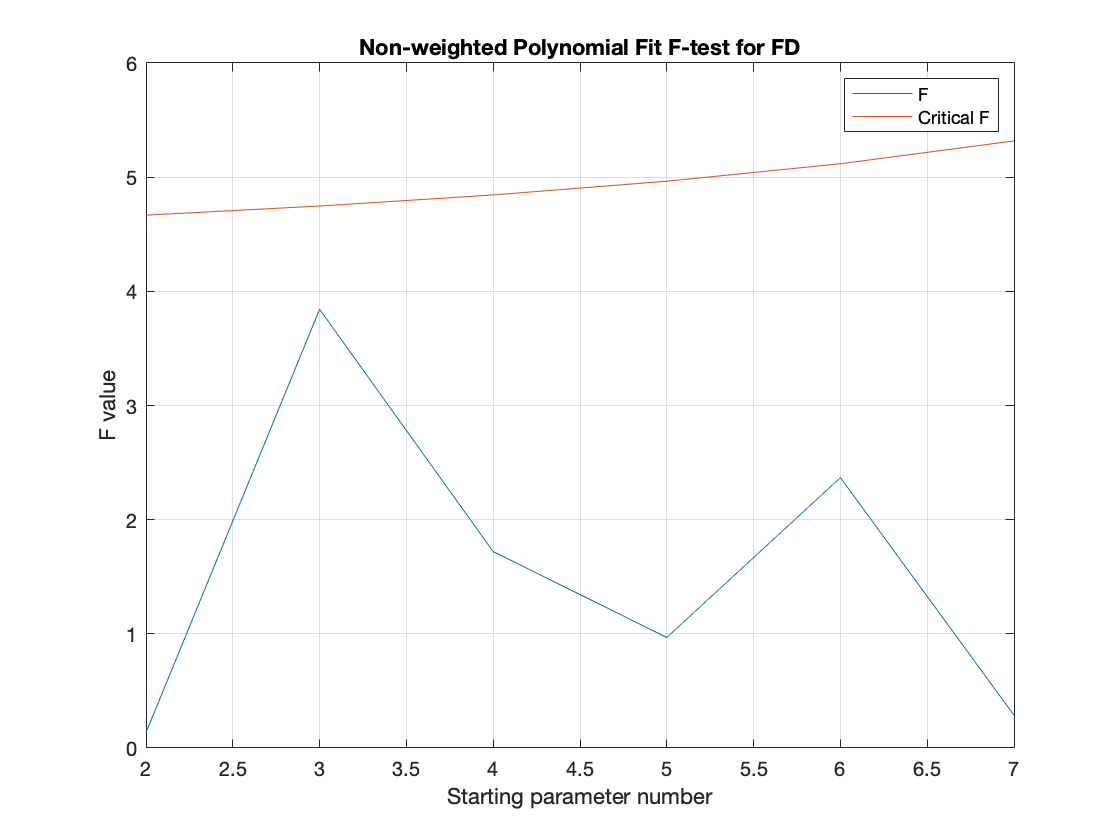

p_plot = 1:1:p;
figure(2);
plot(p_plot+1,F);
hold on; grid on;
plot(p_plot+1,F_crit);
title(strcat("Non-weighted Polynomial Fit F-test for ", chain));
xlabel('Starting parameter number');
ylabel('F value');
legend('F','Critical F');
hold off;

## **Non-Weighted Chi^2 Test**

Performs a non-weighted chi^2 test on the data as another test for signiicance 

clearvars -except chain;

%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;

A = [ones(n,1)];
chi2 = [];
chi2_crit = [];

for p = 1:1:2;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*A)*A'*y; %unweighted
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    chi2 = [chi2, sum(((y - ym)./err).^2)];
    clear ym;
end
p_plot = 2:1:p+1;
figure(3);
plot(p_plot,chi2);
grid on;
title(strcat(chain, ': Chi^2 vs Number of Parameters'));
xlabel('Number of parameters');
ylabel('Chi^2');
hold off;

## **Non-Weighted Standard Deviation**

Finds the Non-weighted standard deviations of the data from the non-weighted regression models with each added parameter 

clearvars -except chain;

%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;

A = [ones(n,1)];
sig = [];

for p = 1:1:5;
    ym = 0;
    A = [A,x.^p]; 
    coef = inv(A'*A)*A'*y; %unweighted
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    sig = [sig, sqrt(sum((y - ym).^2)./(n-(p+1)))];%unweighted
    clear ym;
end
p_plot = 2:1:p+1;
figure(4);
plot(p_plot,sig);
grid on;
title(strcat(chain, ': Non-weighted Standard Devation vs Number of Parameters'));
xlabel('Number of parameters');
ylabel('Standard deviation (Myr)');

## Performing a Non-Weighted Regression on the Data

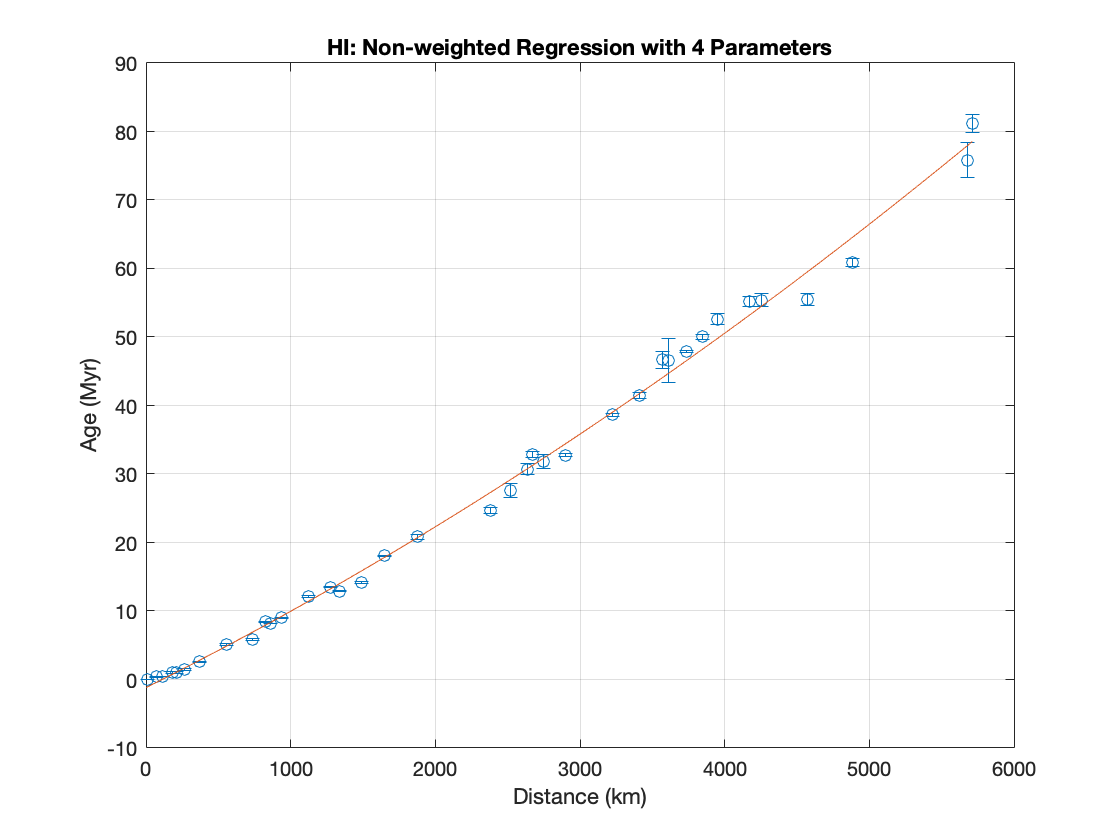

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);

x_plot = 0:1:max(x)+1;

A = [ones(n,1)];

%number of parameters = j+1
for j = 1:1:2;
    clear ym;
    A = [A, x.^j];
    coef = inv(A'*A)*A'*y;%unweighted
    ym = coef(1);
    for p = 2:1:j+1;
        ym = ym + coef(p).*x_plot.^(p-1);
    end
end


figure(5);
errorbar(x,y,err,'o');
hold on; grid on;
plot(x_plot,ym);
title(strcat(chain, ': Non-weighted Regression with 4 Parameters'))
xlabel('Distance (km)');
ylabel('Age (Myr)');
hold off;

## **Fixing Error Bars to be Consistant with Standard Devations about the Non-Weighted Regression Model**

A standard deviation from the chosen parameter value from the non-weighted models from above are used a minumum value for the error of datapoints. Any point with an error below that will be assigned this standard deviation value.

#### Chosen parameter values:

HI: 3

LV: 3

CB: 3

SA: 2

RU: 2

CR: 2

PC: 2

MQ: 2

FD: 2

RU1: 2

RU2: 3

KO: 2

SO: 2

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_consol50.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
type = dat(:,4);
n = length(x);
alpha = 0.95;

%save origonal data
x0 = dat(:,1);
y0 = dat(:,2);
err0 = dat(:,3);

A = [ones(n,1)];
sig = [];

%for loop to give sigma vs parameter set
for p = 1:1:7;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*A)*A'*y; %unweighted
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    sig = [sig, sqrt(sum((y - ym).^2)./(n-(p+1)))];
    clear ym;
end

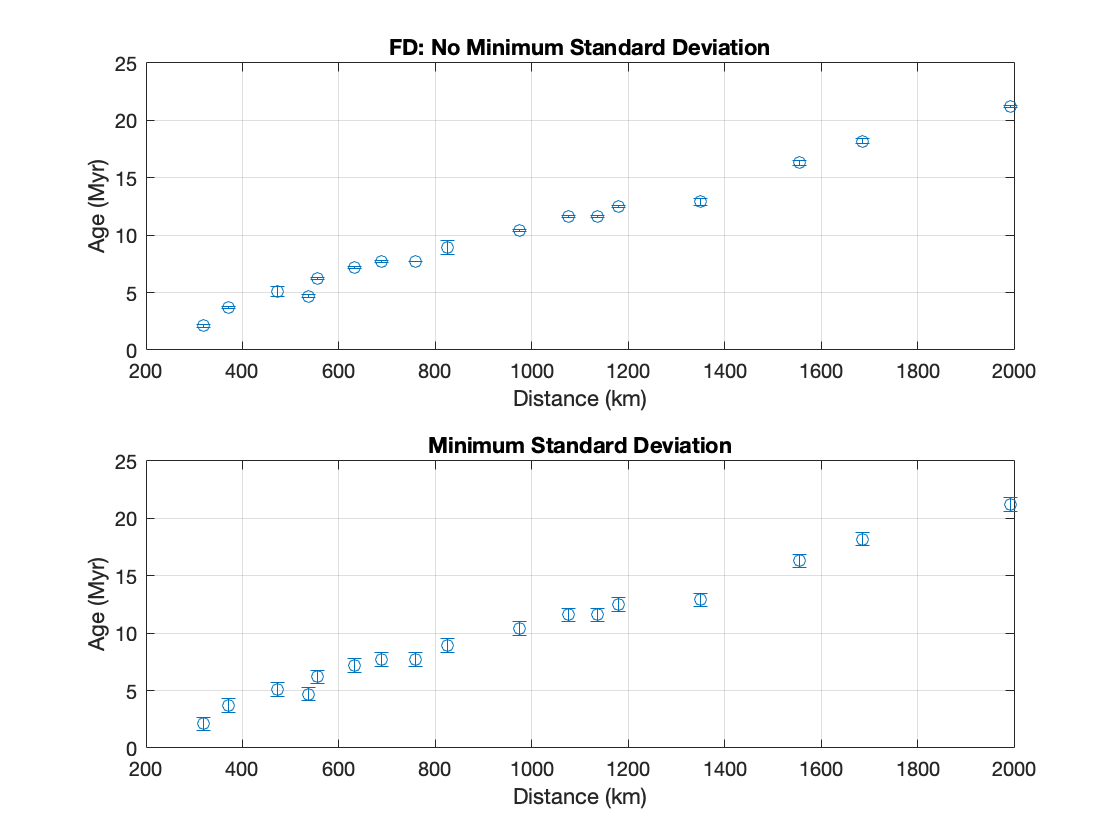


for j = 1:1:length(err);
    if err(j) < sig(1); %parameter value is +1 of index value
        err(j) = sig(1);
    else;
        err(j) = err(j);%DONT CHANGE THIS ONE
    end
end

%expoort as a text file
A = table(x,y,err,type);
writetable(A, strcat('chain_ages/', chain, '_age_dist_copy_final_50km.txt'),'Delimiter','\t','WriteVariableNames',false);

%plot results over original dataset
figure(6);
subplot(211);
errorbar(x0,y0,err0,'o');
grid on;
xlabel('Distance (km)');
ylabel('Age (Myr)');
%set(gca,'xtick',[0:s:max(x0)+s]);
title(strcat(chain, ': No Minimum Standard Deviation'));

subplot(212);
errorbar(x,y,err,'o');
grid on;
xlabel('Distance (km)');
ylabel('Age (Myr)');
%set(gca,'xtick',[0:s:max(x0)+s]);
title('Minimum Standard Deviation');
hold off;

# **Repeat Signifcance Test and Regression Models with Improved Data Set but with Weighted Methods**

## **Weighted F-Test**

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_final_50km.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
y_bar = mean(y);
alpha = 0.95;
q = 1;

w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weight

%weighted degress of freedom
n_eff = (sum(w).^2)./sum(w.^2);

%allocate storage
A1 = [ones(n,1)];
F = [];
F_crit = [];

for p = 1:1:4;
    %allocate storage for model values
    ym1 = 0;
    ym2 = 0;
    %find coefficents for p and p+q
    A1 = [A1,x.^p];
    A2 = [A1,x.^(p+q)];
    coef1 = inv(A1'*W'*W*A1)*A1'*W'*W*y; %weighted 
    coef2 = inv(A2'*W'*W*A2)*A2'*W'*W*y;
    %calculate model values
    for i = 0:1:p;
        ym1 = ym1 + coef1(i+1).*x.^i;
    end
    for j = 0:1:p+q;
        ym2 = ym2 + coef2(j+1).*x.^j;
    end
    %perform F-test using model values
    R_p = sum(((ym1 - y_bar).*w).^2)/sum(((y - y_bar).*w).^2);%weighted
    R_p_q = sum(((ym2 - y_bar).*w).^2)/sum(((y - y_bar).*w).^2);
    ESS_p = R_p*100;
    ESS_p_q = R_p_q*100;
    F = [F, abs(((ESS_p_q - ESS_p)/q)/((100 - ESS_p_q)/(n_eff - (p+1) - q - 1)))];
    F_crit = [F_crit, finv(alpha,q,n_eff-q-(p+1)-1)];
    % get rid of model values for next iteration
    clear ym1;
    clear ym2;
end

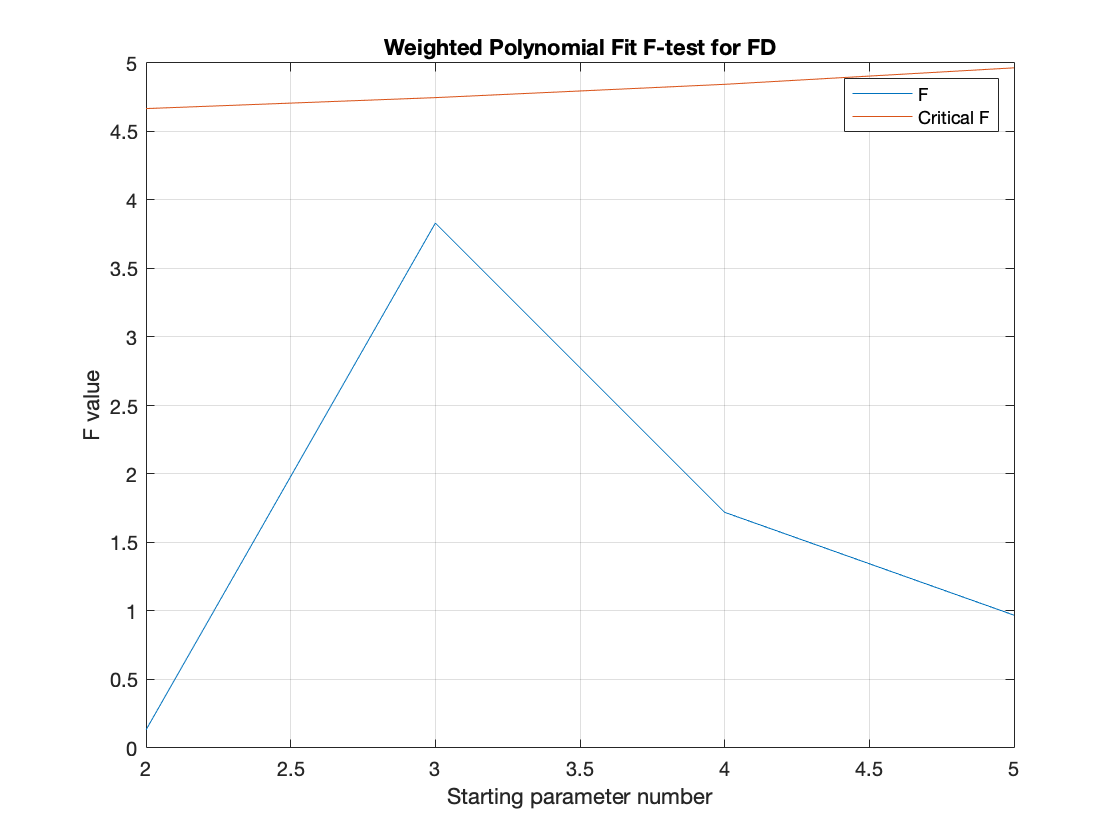

p_plot = 1:1:p;
figure(7);
plot(p_plot+1,F);
hold on; grid on;
plot(p_plot+1,F_crit);
title(strcat("Weighted Polynomial Fit F-test for ", chain));
xlabel('Starting parameter number');
ylabel('F value');
legend('F','Critical F');
hold off;

## Weighted Chi^2 Test

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_final_50km.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;


w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weight


A = [ones(n,1)];
chi2 = [];
chi2_crit = [];

for p = 1:1:4;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted 
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    chi2 = [chi2, sum(((y - ym)./err).^2)];
    clear ym;
end
p_plot = 2:1:p+1;
figure(8);
plot(p_plot,chi2);
hold on; grid on;
title(strcat(chain, ': Chi^2 vs Number of Parameters'));
xlabel('Number of parameters');
ylabel('Chi^2');
hold off;

## Weighted Standard Deviation 

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_final_50km.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;


w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weight

%weighted degress of freedom
n_eff = (sum(w).^2)./sum(w.^2);

A = [ones(n,1)];
sig = [];

for p = 1:1:5;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted 
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    sy = sum((abs(y - ym)).*w);%weighted
    sw = sum(w);
    syy = sum(w.*(abs(y - ym)).^2);
    sig = [sig, (sw.*syy - sy.^2)./(((n_eff-1)./n_eff).*sw.^2)];
    clear ym;
end
p_plot = 2:1:p+1;
figure(9);
plot(p_plot,sig);
grid on;
title(strcat(chain, ': Weighted Standard Devation vs Number of Parameters'));
xlabel('Number of parameters');
ylabel('Standard deviation (Myr)');
hold off;

## Weighted Regression Model

clearvars -except chain;
%import data
dat = importdata(strcat('chain_ages/', chain, '_age_dist_copy_final_50km.txt'));%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
y_bar = mean(y);

%set weights
w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weights

x_plot = 0:1:max(x)+1;

A = [ones(n,1)];

%number of parameters = j+1
for j = 1:1:2;
    clear ym;
    A = [A, x.^j];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted
    ym = coef(1);
    for p = 2:1:j+1;
        ym = ym + coef(p).*x_plot.^(p-1);
    end
end


figure(10);
errorbar(x,y,err,'o');
hold on; grid on;
plot(x_plot,ym);
title(strcat(chain, ': Weighted with 3 Parameters'))
xlabel('Distance (km)');
ylabel('Age (Myr)');
hold off;

# Standard Deviation Statistics

## Take a non-weighted standard deviation of the weighted regressions

clear;

%import data

dat = importdata('chain_ages/HI_age_dist_copy_final_50km.txt');%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;


w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weight

A = [ones(n,1)];
sig = [];

for p = 1:1:5;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted 
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
    sig = [sig, sqrt(sum((y - ym).^2)./(n-(p+1)))];%unweighted
    clear ym;
end
p_plot = 2:1:p+1;
figure(11);
plot(p_plot,sig);
grid on;
title('Standard Devation vs Number of Parameters');
xlabel('Number of parameters');
ylabel('Standard deviation (Myr)');

## To Make a Table of all data deviations from regression

clear;

%import data

dat = importdata('chain_ages/SA_age_dist_copy_final_50km.txt');%consolidated data

%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
alpha = 0.95;


w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weight

A = [ones(n,1)];
sig = [];

for p = 1:1:1;
    ym = 0;
    A = [A,x.^p];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted 
    for i = 0:1:p;
        ym = ym + coef(i+1).*x.^i;
    end
end
sig = y - ym


## Histogram of Deviations

clear;

dat = importdata('chain_ages/age_deviations.txt');

mean(dat)
std(dat)

figure(12);
histogram(dat,[-7:0.25:7]);
title('Age Deviations from Regression Model for all Pacific Chains')
xlabel('Age Deviation (Myr)');
ylabel('Frequency');

## Adding confidence intervals to the regression curves

clear;
%import data
dat = importdata('chain_ages/PC_age_dist_copy_final_50km.txt');%consolidated data


%organize Columns
x = dat(:,1);
y = dat(:,2);
err = dat(:,3);
n = length(x);
y_bar = mean(y);

alpha1 = 0.95;
alpha2 = 0.99;

%set weights
w = 1./err;%set weight as 1/error
w = w./sum(w);%make weights sum to 1
W = diag(w);%create the diagnal matrix of weights

%weighted degress of freedom
n_eff = (sum(w).^2)./sum(w.^2);

x_plot = 0:1:max(x)+1;

A = [ones(n,1)];

%number of parameters = j+1
for j = 1:1:1;
    clear ym;
    A = [A, x.^j];
    coef = inv(A'*W'*W*A)*A'*W'*W*y; %weighted
    ym = coef(1);
    for p = 2:1:j+1;
        ym = ym + coef(p).*x_plot.^(p-1);
    end
end

coef = flip(coef);

[p,s] = polyfit(x,y,1);
[Y1, delta1] = polyconf(coef,x_plot,s);
[Y2, delta2] = polyconf(coef,x_plot,s,'alpha',0.01);

y_plus_95 = ym + delta1;
y_minus_95 = ym - delta1;

y_plus_99 = ym + delta2;
y_minus_99 = ym - delta2;

figure(13);
errorbar(x,y,err,'o');
hold on; grid on;
m = plot(x_plot,ym);
p_95 = plot(x_plot,y_plus_95,'-- black',x_plot,y_minus_95,'-- black');
p_99 = plot(x_plot,y_plus_99,'-- red',x_plot,y_minus_99,'-- red');
title('Pitcairn Age Progression Curve')
xlabel('Distance (km)');
ylabel('Age (Myr)');
legend([m p_95(1) p_99(1)],'2 parameter model','95% confidence','99% confidence')
hold off;

# Testing the Combined Chain Info File

clear;

dat = importdata('chain_age_dist_tables/HI_line_age.txt');
x = dat(:,3);
y = dat(:,7);
y_low = dat(:,8);
y_high = dat(:,9);

dat2 = importdata('chain_ages/HI_age_dist_copy_final_50km.txt');

figure(14);
errorbar(dat2(:,1),dat2(:,2), dat2(:,3),'o');
grid on;
hold on;
plot(x,y);
plot(x,y_low,'black --');
plot(x,y_high,'black --');
hold off;